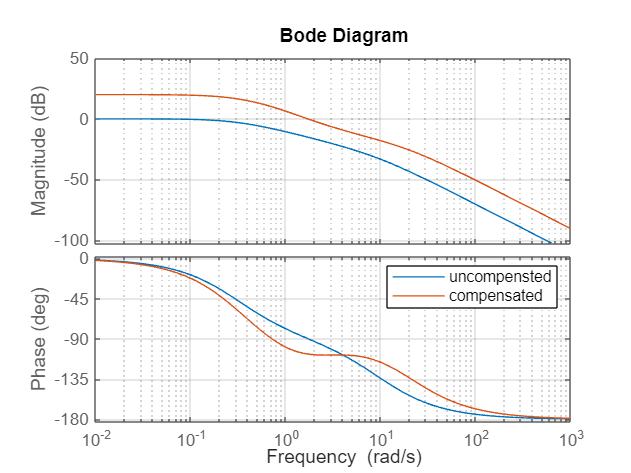

%NAME: WYCLIFFE MACHUKI OKENYE
%REG: EG209/106813/21
%CONTROL ASSIGNMENT

% Case 1: G1(s) = 9/(s^2 + 4 s + 9)
s = tf('s');
G1 = 3/(s^2 + 10*s + 3);%%open loopTf for uncompensated sytem

% Proposed compensators
C_lead = 10*(s+2)/(s+15);%%lead comaparator
C_lag  = (s+5)/(s+0.5);
C_T= C_lead * C_lag;%%lead and lag in cascade

% Closed-loop (unity feedback)
T1 = feedback(C_T * G1, 1);


% bode plot for uncompenated system and compensated system
figure;
bode(G1, C_T*G1); 
legend('uncompensted','compensated');
grid on;

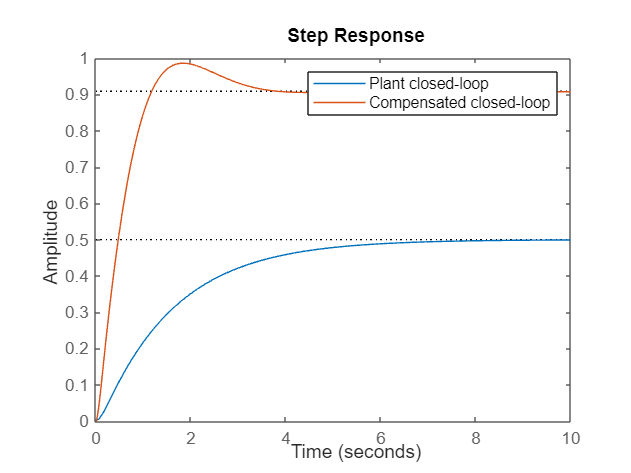

Step info for compensated case 1:


         RiseTime: 0.8275
    TransientTime: 3.1041
     SettlingTime: 3.1041
      SettlingMin: 0.8184
      SettlingMax: 0.9863
        Overshoot: 8.4894
       Undershoot: 0
             Peak: 0.9863
         PeakTime: 1.8403



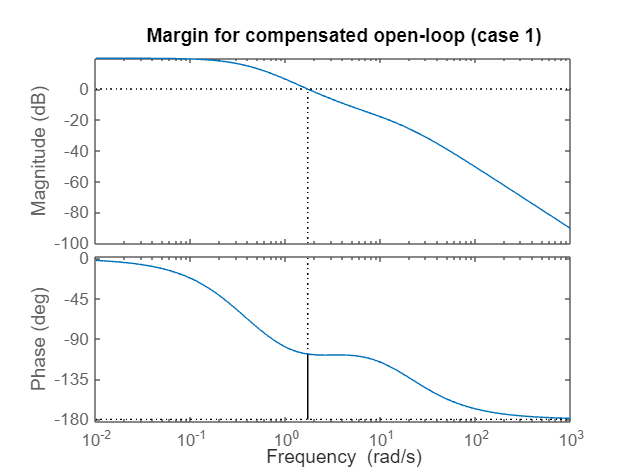

%%step polots for uncompensatedand fully_compensted system
figure; 
step(G1/(1+G1), T1); 
legend('Plant closed-loop','Compensated closed-loop');